load flip_eqns.mat
load contact_eqns.mat
load roll_eqns.mat
load design_parameters.mat
syms s_contact1 s_contact2 ta23 tv23 t23 t1 t2 t3 t4 t5 t6
syms rw r2 r3 r5 l7_ab I7 m1 m2 m3 m4 m5 m6 m7 I1 I2 I3 I4 I5 I6 g2 C_friction7 ta13 a51 tv13 t13 T_z height1 length1 wheel_density frame_density gear_density gear_thickness frame_thickness wheel_thickness

step_height = 0.15;
rw_sim = 0.075;
rectangle_width = 0.085;


%apply to eqs
Q_eqn1=subs(flip_eqns, lhs(design_parameters), rhs(design_parameters));
%Q_eqn1= ta13 == simplify(rhs(Q_eqn1));

Q_eqn2=subs(contact_eqns, lhs(design_parameters), rhs(design_parameters));
%Q_eqn2= Q_eqn2(1);

Q_eqn3=subs(roll_eqns, lhs(design_parameters), rhs(design_parameters));
%Q_eqn3= Q_eqn3(1);

%Assign torque
Torque = 1.8; %Nm
Q_eqn1=subs(Q_eqn1, T_z, Torque);
%Q_eqn1= ta13 == simplify(rhs(Q_eqn1));

Q_eqn2=subs(Q_eqn2, T_z, Torque);
Q_eqn3=subs(Q_eqn3, T_z, Torque);
%Q_eqn2= ta13 == simplify(rhs(Q_eqn2))
%R_eqn=subs(roll_eqns, lhs(design_parameters), rhs(design_parameters))
%R_eqn= lhs(R_eqn) == simplify(rhs(R_eqn))

%Calculate threshold
contact_threshold = pi-atan((step_height-rw_sim)/rw_sim)-asin(rectangle_width/(2*sqrt((step_height-rw_sim).^2+rw_sim.^2)));
contact_point = [r2+2*r3+r5-sqrt((step_height-rw_sim).^2+rw_sim.^2-(rectangle_width/2).^2); rectangle_width/2];
hyp=contact_point+[r2+2*r3+r5;0]

$$hyp = \left(\begin{array}{c} 2\,r_{2}+4\,r_{3}+2\,r_{5}-\frac{7002481949836663}{72057594037927936}\\ \frac{17}{400} \end{array}\right)$$

hyp=sqrt(hyp(1).^2+hyp(2).^2)

$$hyp = \sqrt{{\left(2\,r_{2}+4\,r_{3}+2\,r_{5}-\frac{7002481949836663}{72057594037927936}\right)}^{2}+\frac{289}{160000}}$$

wheel_threshold = pi/2+asin(rectangle_width/(2*hyp))+acos(rw_sim/hyp)

$$wheel\_threshold = \frac{\pi }{2}+\mathrm{acos}\left(\frac{3}{40\,\sqrt{{\left(2\,r_{2}+4\,r_{3}+2\,r_{5}-\frac{7002481949836663}{72057594037927936}\right)}^{2}+\frac{289}{160000}}}\right)+\mathrm{asin}\left(\frac{17}{400\,\sqrt{{\left(2\,r_{2}+4\,r_{3}+2\,r_{5}-\frac{7002481949836663}{72057594037927936}\right)}^{2}+\frac{289}{160000}}}\right)$$

wheel_threshold= double(subs(wheel_threshold,lhs(design_parameters), rhs(design_parameters)));
landing_pos = sqrt(hyp.^2-rw_sim.^2)

$$landing\_pos = \sqrt{{\left(2\,r_{2}+4\,r_{3}+2\,r_{5}-\frac{7002481949836663}{72057594037927936}\right)}^{2}-\frac{611}{160000}}$$

syms u [4 1]
syms rk_eq1(u)
syms rk_eq2(u)


f= rhs(subs(Q_eqn1,[t13, tv13, t23, tv23], [u1, u2, u3, u4]));

rk_eq1(u1, u2, u3, u4) = [u2;f(1);u4;f(2)];

f= rhs(subs(Q_eqn2,[t13, tv13, t23, tv23], [u1, u2, u3, u4]));
f= subs(f,[s_contact1; s_contact2], contact_point);
f= subs(f,lhs(design_parameters), rhs(design_parameters));
rk_eq2(u1, u2, u3, u4) = [u2;f(1);u4;f(2)];

f= rhs(subs(Q_eqn3,[t13, tv13, t23, tv23], [u1-pi, u2, u3, u4]));

rk_eq3(u1, u2, u3, u4) = [u2;f(1);u4;f(2)];



Step_Value = 0.005;
t_beg = 0;
t_end = 1;
t_intial=0;
u_intial=[0,0,0,0];
% Routine starts here
h=Step_Value;
t=t_beg:h:t_end;
u=zeros(4,length(t));
u(:,1)=u_intial;
contact_time=length(t)+1

contact_time = 202

wheel_time= length(t)+1

wheel_time = 202


stage=1;

for i=1:(length(t)-1)
    t0=t(i);
    up1=u(1,i);
    up2=u(2,i);
    up3=u(3,i);
    up4=u(4,i);
    if stage == 1
        k1 = double(rk_eq1(up1, up2, up3, up4));
        k2 = double(rk_eq1(up1+0.5*h*k1(1), up2+0.5*h*k1(2), up3+0.5*h*k1(3),up4+0.5*h*k1(4)));
        k3 = double(rk_eq1(up1+0.5*h*k2(1), up2+0.5*h*k2(2), up3+0.5*h*k2(3),up4+0.5*h*k2(4)));
        k4 = double(rk_eq1(up1+k3(1)*h, up2+k3(2)*h, up3+k3(3)*h, up4+k3(4)*h));
        u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
        if u(1,i) >= contact_threshold
            stage = 2;
            contact_time = i
        end
    
    elseif stage == 2
        k1 = double(rk_eq2(up1, up2, up3, up4))
        k2 = double(rk_eq2(up1+0.5*h*k1(1), up2+0.5*h*k1(2), up3+0.5*h*k1(3),up4+0.5*h*k1(4)))
        k3 = double(rk_eq2(up1+0.5*h*k2(1), up2+0.5*h*k2(2), up3+0.5*h*k2(3),up4+0.5*h*k2(4)))
        k4 = double(rk_eq2(up1+k3(1)*h, up2+k3(2)*h, up3+k3(3)*h, up4+k3(4)*h))
        u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
        if u(1,i) >= wheel_threshold
            stage = 3;
            wheel_time = i
            u(4,i+1) = 0;
        end
    elseif stage == 3
        k1 = double(rk_eq3(up1, up2, up3, up4));
        k2 = double(rk_eq3(up1+0.5*h*k1(1), up2+0.5*h*k1(2), up3+0.5*h*k1(3),up4+0.5*h*k1(4)));
        k3 = double(rk_eq3(up1+0.5*h*k2(1), up2+0.5*h*k2(2), up3+0.5*h*k2(3),up4+0.5*h*k2(4)));
        k4 = double(rk_eq3(up1+k3(1)*h, up2+k3(2)*h, up3+k3(3)*h, up4+k3(4)*h));
        u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
        i
    end
end

contact_time = 140

k1 = 1.0e+08 *

    0.0000
   -0.0000
    0.0000
    6.4939


k2 = 1.0e+08 *

    0.0000
   -0.0000
    0.0162
    6.4939


k3 = 1.0e+08 *

    0.0000
   -0.0000
    0.0162
    6.4939


k4 = 1.0e+08 *

    0.0000
   -0.0000
    0.0325
    6.4939


k1 = 1.0e+08 *

    0.0000
   -0.0000
    0.0325
    6.4939


k2 = 1.0e+08 *

    0.0000
   -0.0000
    0.0487
    6.4939


k3 = 1.0e+08 *

    0.0000
   -0.0000
    0.0487
    6.4939


k4 = 1.0e+08 *

    0.0000
   -0.0000
    0.0649
    6.4939


k1 = 1.0e+08 *

    0.0000
   -0.0000
    0.0649
    6.4939


k2 = 1.0e+08 *

    0.0000
   -0.0000
    0.0812
    6.4939


k3 = 1.0e+08 *

    0.0000
   -0.0000
    0.0812
    6.4939


k4 = 1.0e+08 *

    0.0000
   -0.0000
    0.0974
    6.4939


k1 = 1.0e+08 *

    0.0000
   -0.0000
    0.0974
    6.4939


k2 = 1.0e+08 *

    0.0000
   -0.0000
    0.1136
    6.4939


k3 = 1.0e+08 *

    0.0000
   -0.0000
    0.1136
    6.4939


k4 = 1.0e+08 *

    0.0000
   -0.0000
    0.1299
    6.4939


k1 = 1.0e+08 *

    0.0000
   -0.0000
    0.1299
    6.4939


k2 = 1.0e+08 *

    0.0000
    0.0000
    0.1461
    6.4939


k3 = 1.0e+08 *

    0.0000
    0.0000
    0.1461
    6.4939


k4 = 1.0e+08 *

    0.0000
    0.0000
    0.1623
    6.4939


k1 = 1.0e+08 *

    0.0000
    0.0000
    0.1623
    6.4939


k2 = 1.0e+08 *

    0.0000
    0.0000
    0.1786
    6.4939


k3 = 1.0e+08 *

    0.0000
    0.0000
    0.1786
    6.4939


k4 = 1.0e+08 *

    0.0000
    0.0000
    0.1948
    6.4939


k1 = 1.0e+08 *

    0.0000
    0.0000
    0.1948
    6.4939


k2 = 1.0e+08 *

    0.0000
    0.0000
    0.2111
    6.4939


k3 = 1.0e+08 *

    0.0000
    0.0000
    0.2111
    6.4939


k4 = 1.0e+08 *

    0.0000
    0.0000
    0.2273
    6.4939


k1 = 1.0e+08 *

    0.0000
    0.0000
    0.2273
    6.4939


k2 = 1.0e+08 *

    0.0000
    0.0000
    0.2435
    6.4939


k3 = 1.0e+08 *

    0.0000
    0.0000
    0.2435
    6.4939


k4 = 1.0e+08 *

    0.0000
    0.0000
    0.2598
    6.4939


wheel_time = 148

i = 149

i = 150

i = 151

i = 152

i = 153

i = 154

i = 155

i = 156

i = 157

i = 158

i = 159

i = 160

i = 161

i = 162

i = 163

i = 164

i = 165

i = 166

i = 167

i = 168

i = 169

i = 170

i = 171

i = 172

i = 173

i = 174

i = 175

i = 176

i = 177

i = 178

i = 179

i = 180

i = 181

i = 182

i = 183

i = 184

u

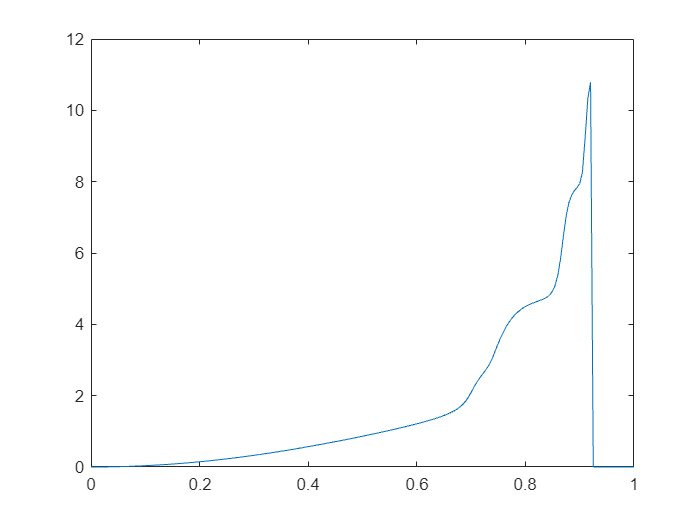


plot(t,u(1,:))


%pre contact
s5(t13)=[0, rw];
s2(t13)=s5 + (r5+2*r3+r2)*[-cos(t13), sin(t13)];
s6(t13)=s5 + 2*(r5+2*r3+r2)*[-cos(t13), sin(t13)];
s2(t13)=subs(s2,lhs(design_parameters), rhs(design_parameters));
s5(t13)=subs(s5,lhs(design_parameters), rhs(design_parameters));
s6(t13)=subs(s6,lhs(design_parameters), rhs(design_parameters));

%post contact

Rz = [cos(t13), sin(t13), 0;
    -sin(t13), cos(t13), 0;
    0, 0, 1];


eq=-Rz*[contact_point;0];
s22(t13)=eq(1:2).';
s22(t13)=s22(t13)+[rw_sim, step_height];
s52(t13)=s22 - (r5+2*r3+r2)*[-cos(t13), sin(t13)];
s62(t13)=s22 + (r5+2*r3+r2)*[-cos(t13), sin(t13)];
s22(t13)=subs(s22,lhs(design_parameters), rhs(design_parameters));
s52(t13)=subs(s52,lhs(design_parameters), rhs(design_parameters));
s62(t13)=subs(s62,lhs(design_parameters), rhs(design_parameters));





t_eqns = [t3-t1 == -r2/r3*(t2-t1);
    t4-t1 == -r2/r3*(t2-t1);
    t5-t1 == -r3/r5*(t3-t1);
    t6-t1 == -r3/r5*(t4-t1);
    ];
t_eqns(1)=isolate(t_eqns(1),t3);
t_eqns(2)=isolate(t_eqns(2),t4);
t_eqns(3)=isolate(t_eqns(3),t5);
t_eqns(4)=isolate(t_eqns(4),t6);

t_eqns(3)=subs(t_eqns(3),lhs(t_eqns(1)), rhs(t_eqns(1)));
t_eqns(4)=subs(t_eqns(4),lhs(t_eqns(2)), rhs(t_eqns(2)));

theta5(t1,t2)=rhs(t_eqns(3));
theta6(t1,t2)=rhs(t_eqns(4));
theta5(t1,t2)=subs(theta5(t1,t2),lhs(design_parameters), rhs(design_parameters));
theta6(t1,t2)=subs(theta6(t1,t2),lhs(design_parameters), rhs(design_parameters));

s63(t1, t2)=[rw*t6+landing_pos+rw_sim, rw+step_height];
s63(t1, t2)=subs(s63(t1, t2),lhs(t_eqns(4)), rhs(t_eqns(4)));

s23(t1, t2)=s63(t1, t2) - (r5+2*r3+r2)*[-cos(t1), sin(t1)];
s53(t1, t2)=s63(t1, t2) - 2*(r5+2*r3+r2)*[-cos(t1), sin(t1)];
s23(t1, t2)=subs(s23,lhs(design_parameters), rhs(design_parameters));
s53(t1, t2)=subs(s53,lhs(design_parameters), rhs(design_parameters));
s63(t1, t2)=subs(s63,lhs(design_parameters), rhs(design_parameters));



p2=zeros(2,length(t));
p5=zeros(2,length(t));
p6=zeros(2,length(t));
thetas5=zeros(1,length(t));
thetas6=zeros(1,length(t));
tests=zeros(1,length(t));

for i=1:length(t)
    if i< contact_time
        p5(:,i)=double(s5(u(1,i)));
        p2(:,i)=double(s2(u(1,i)));
        p6(:,i)=double(s6(u(1,i)));
    elseif i< wheel_time
        p5(:,i)=double(s52(u(1,i)));
        p2(:,i)=double(s22(u(1,i)));
        p6(:,i)=double(s62(u(1,i)));
    else
        p5(:,i)=double(s53(u(1,i), u(3,i)));
        p2(:,i)=double(s23(u(1,i), u(3,i)));
        p6(:,i)=double(s63(u(1,i), u(3,i)));
    end
    thetas5(i)=double(theta5(u(1,i), u(3,i)));
    thetas6(i)=double(theta6(u(1,i), u(3,i)));
end
thetas5

thetas5 = 1.0e+06 *

         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


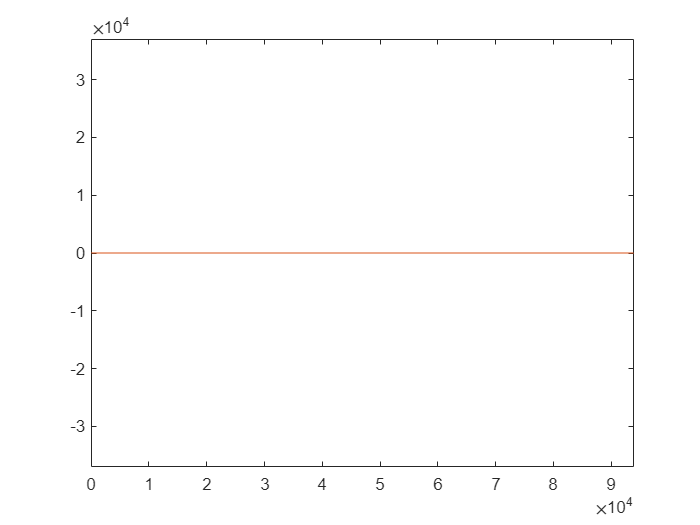


plot(p2(1,:), p2(2,:))
axis equal
hold on
plot(p6(1,:), p6(2,:))
hold off


F(length(t)) = struct('cdata',[],'colormap',[]);
for j=1:length(t)
    f=figure('visible','off');
    hold on;
    %wheels
    circle(p6(1,j), p6(2,j), rw_sim);
    line([p6(1,j),p6(1,j)+rw_sim*cos(thetas5(j))],[p6(2,j),p6(2,j)-rw_sim*sin(thetas5(j))])
    
    circle(p5(1,j), p5(2,j), rw_sim);
    line([p5(1,j),p5(1,j)+rw_sim*cos(thetas5(j))],[p5(2,j),p5(2,j)-rw_sim*sin(thetas5(j))])

    %frame
    corner(:,1) = [p6(1,j)+rectangle_width/2*sin(u(1,j)); p6(2,j)+rectangle_width/2*cos(u(1,j))];
    corner(:,2) = [p6(1,j)-rectangle_width/2*sin(u(1,j)); p6(2,j)-rectangle_width/2*cos(u(1,j))];
    corner(:,3) = [p5(1,j)-rectangle_width/2*sin(u(1,j)); p5(2,j)-rectangle_width/2*cos(u(1,j))];
    corner(:,4) = [p5(1,j)+rectangle_width/2*sin(u(1,j)); p5(2,j)+rectangle_width/2*cos(u(1,j))];
    corner(:,5) = corner(:,1);
    line(corner(1,:), corner(2,:))


    axis equal;
    xlim([-0.3,0.3])
    ylim([-0.1, 0.5])
    line([rw_sim, rw_sim], [0, step_height])
    line([rw_sim, 3], [step_height, step_height])
    hold off;
    F(j) = getframe(gcf);
end

fig = figure;


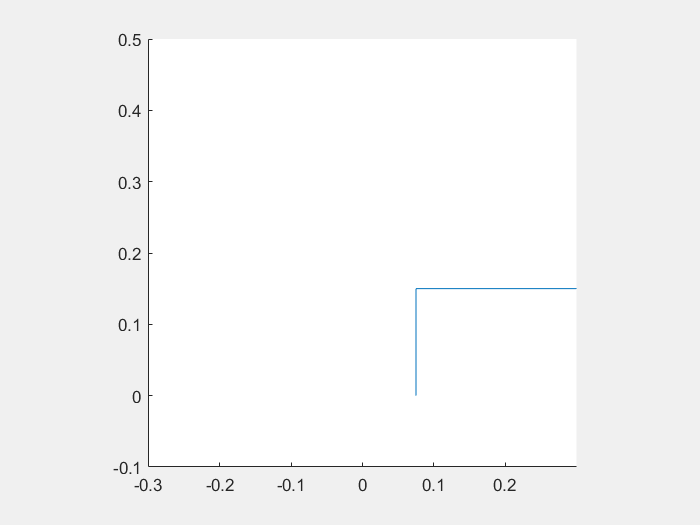


movie(fig, F, 1, 1/h);

function h = circle(x,y,r)
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit);
end